#### Osservatore

L’osservatore è un sistema dinamico che prende due ingressi ovvero l’uscita misurata e l’ingresso di controllo e sulla base di questi restituisce uno stato osservato, ovvero uno stato ricostruito dal sistema dinamico. Un sistema lineare è osservabile se e solo se per ogni istante $T>0$, è possibile determinare lo stato del sistema $x(T)$ a questo istante terminale solamente ed esclusivamente attraverso delle misurazioni di $y$ e $u$ nell'intervallo temporale $\left\lbrack 0,T\right\rbrack$. Se il sistema è osservabile allora esiste una trasformazione $T$ tale che $z=\textrm{Tx}$ che porta il sistema in forma canonica di osservabilità. La matrice di osservabilità è pari a : $W_O = [C \space CA ... CA^{n -1}]^T$. Come per la raggiungibilità, un sistema è osservabile se la sua matrice di osservabilità ha rango pieno, quindi dobbiamo verificare che il rango sia pari a $n$. Si indica invece con $\tilde W_O$ la matrice di osservabilità in forma canonica.

Se il sistema è osservabile allora

$\dot{\hat x} = A \hat x + Bu + L(y - C \hat x)$ è un osservatore 

in cui

- $\hat x
$ rappresenta la stima delle variabili di stato

- $u$ è l'ingresso di controllo

- $A, B, C$ sono le matrici del modello dinamico del sistema

- $L(y - C \hat x)$ è un termine correttivo sullo stato stimato ed è tanto più grande quanto più grande l’errore tra l’uscita e l'uscita stimata.

Il parametro di progetto in questo caso è $L = W_O ^{-1} \cdot \tilde W_O \cdot  \left[\matrix{ P_1-a_1\cr. \cr . \cr . \cr P_n-a_n} \right]$, in particolare si vanno a scegliere le posizioni desiderate dei poli $P_1,...,P_n$ per fare in modo che l'osservatore sia più veloce della dinamica a ciclo chiuso del sistema osservato: la ragione è molto intuitiva in quanto devo poter avere lo stato disponibile più velocemente di quanto il sistema evolve.

#### Verifica dell'osservabilità e della raggiungibilità

Verifichiamo la raggiungibilità e l'osservabilità del sistema. Poichè sia $W_r
$ che $W_O$ hanno rango pieno possiamo concludere che il sistema è sia raggiungibile che osservabile. Dato che il sistema è raggiungibile e osservabile vale il *principio di separazione* che consente di pensare all'architettura come consistente di due parti: una parte che è il solo osservatore e una parte che è il solo controllore. In particolare, si può procedere alla progettazione del guadagno del controllore facendo finta che lo stato risulti essere completamente misurabile e dopodiché si progettano i guadagni di $L$ che dipendono solo da $A$ e $C$. 

## Fist step: define the system and check for reachability

mkdir('Risultati_OsservatoreLQR');

m = 1; 
l = 1;
b = 0.1;
g = 9.81;

A=[0 1; g/l -b/(m*l^2)];
B=[0; 1/(m*l^2)];
C= [1 0];
D=0;

Wr = [B A*B];
Wr_rank = rank(Wr)

Wr_rank = 2


Wo = [C;C*A];
Wo_rank = rank(Wo)

Wo_rank = 2

Utilizziamo LQR (Regolatore Quadratico Lineare) per trovare la matrice di guadagno `K` che minimizza una funzione di costo definita dalle matrici di pesatura `Qx` e `Qu`. 

% LQR 
% Definizione dei punti di equilibrio
x1_e = pi;
x2_e = 0;

Qx=[ 10 0; 0 0.1];
Qu= 0.015;

% Qz=[ 20 0; 0 0.08];
% Qu= 0.00 3;

[K,S,P] = lqr(A,B,Qx,Qu);

Questa sezione progetta un osservatore utilizzando il comando `place` per posizionare i poli dell'osservatore in posizioni specificate (`p_obs`).

%% The observer will be designed by picking eigenvalues that converge faster...
p_obs = [-600,-800]; % desired poles for the observer
L = place(A.',C.',p_obs);
L=L.';

I poli dell'osservatore sono posti in alta frequenza e sono di due ordini di grandezza superiori rispetto a quelli del sistema per garantire un errore di circa $0\ldotp 07$ tra lo stato osservato e quello vero considerando accettabile come soglia di errore $0\ldotp 1$ 

#### Simulazione e plot

out =   Simulink.SimulationOutput:

                      t: [1221x1 double] 
                   tout: [1221x1 double] 
                      u: [1221x1 double] 
                     x2: [1221x1 double] 
                 x2_hat: [1221x1 double] 
                      y: [1221x1 double] 

     SimulationMetadata: [1x1 Simulink.SimulationMetadata] 
           ErrorMessage: [0x0 char] 


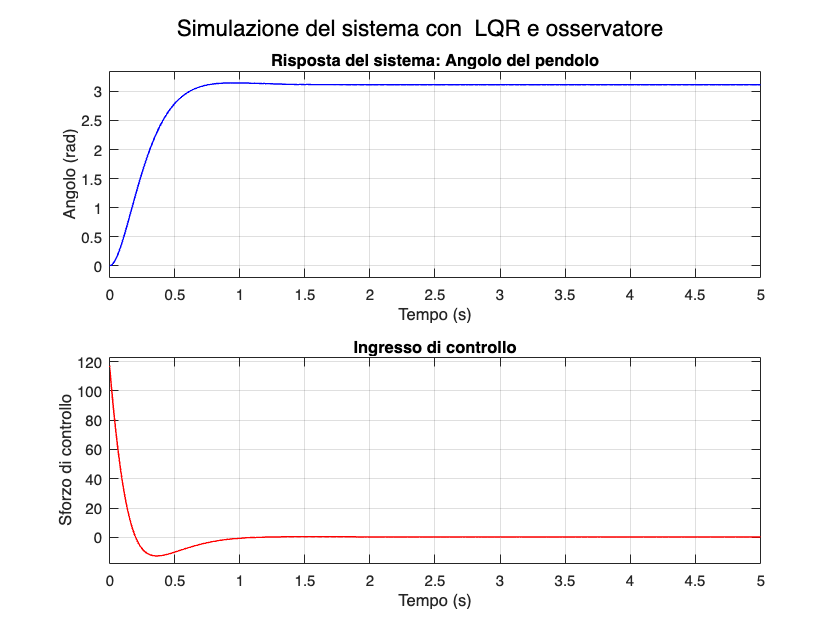


standard_model = 'x2_observer.slx';
out=sim(standard_model,10);

timestamp = datestr(now, 'yyyymmdd_HHMMSS');

% Crea una stringa univoca per il nome del file
imageName = ['Results_', timestamp, '.png'];

% Plot dei dati
plot_data("x2_observer");

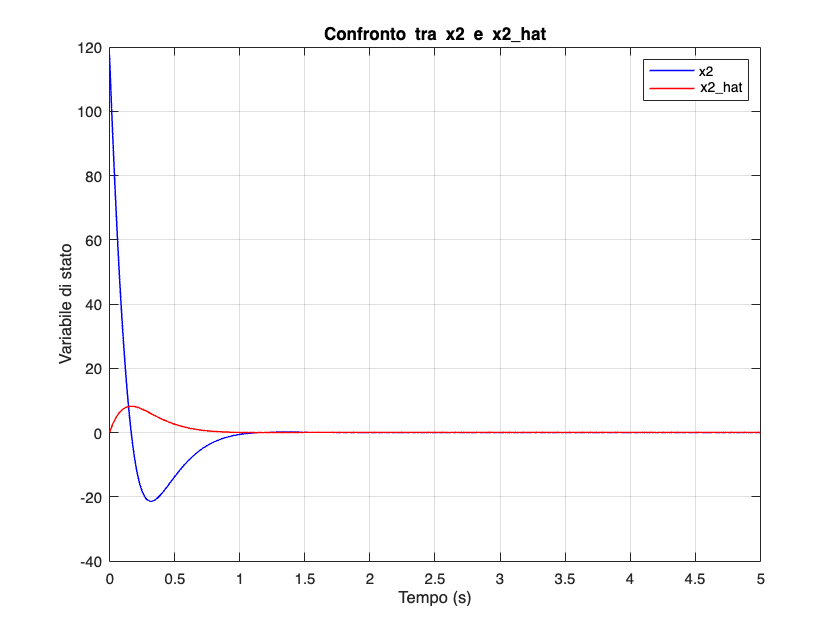


% Salva l'immagine con un nome univoco
saveas(gcf, fullfile('Risultati_OsservatoreLQR', imageName))


results=stepinfo(out.y,out.t);
disp(results)

         RiseTime: 0.4224
    TransientTime: 0.6609
     SettlingTime: 0.6609
      SettlingMin: 2.8112
      SettlingMax: 3.1461
        Overshoot: 1.0778
       Undershoot: 0
             Peak: 3.1461
         PeakTime: 0.9554



obs=stepinfo(out.x2_hat,out.t);
disp(obs)

         RiseTime: 6.1518e-04
    TransientTime: 0.8466
     SettlingTime: 1.9460
      SettlingMin: 0.0183
      SettlingMax: 8.1920
        Overshoot: 9.0141e+03
       Undershoot: 0
             Peak: 8.1920
         PeakTime: 0.1672

